% 回归分析预测工业增加值变化规律
clear all; clc;
% 读取数据
file = '月度数据.xls';
[NUM,~,~]=xlsread(file);

% 缺失值填补，采用线性插补法
d2 = fillmissing(NUM,'linear');

% 数据变换
d3 = d2;
d3(:,end-2:end-1) = []; %删除第二产业增加值和利润
% 人均可支配收入前的空缺行删除，只保留2013-09之后的
index = find(d3(:,11) == 13556.5);
d3(1:index-1,:) = [];
%d3_stan = stan(d3);  %标准化后的数据，min-max标准化

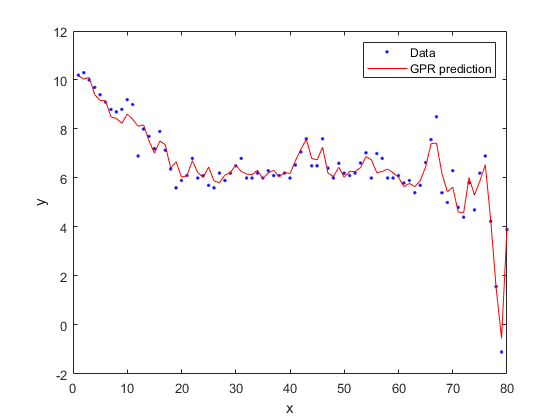

% 模型训练
rng(0,'twister');
%高斯过程回归
[GPR, GPR_RMSE] = GPR_SQ(d3); 
GPRmodel = GPR.RegressionGP;
x = 1:length(d3);
y = d3(:,end); %目标变量
ypre = resubPredict(GPRmodel); %目标变量的预测值
plot(x,y,'b.',x,ypre,'r');
xlabel('x');
ylabel('y');
legend('Data','GPR prediction');
hold off;

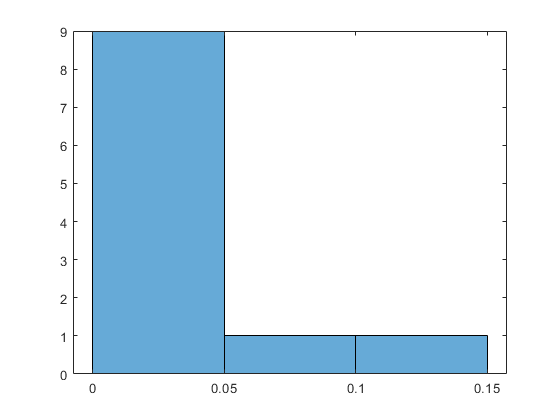

% 决策树
[Dtree, Dtree_RMSE] = DecisionTree(d3);
Dtreemodel = Dtree.RegressionTree;
imp = predictorImportance(Dtreemodel);
histogram(imp);

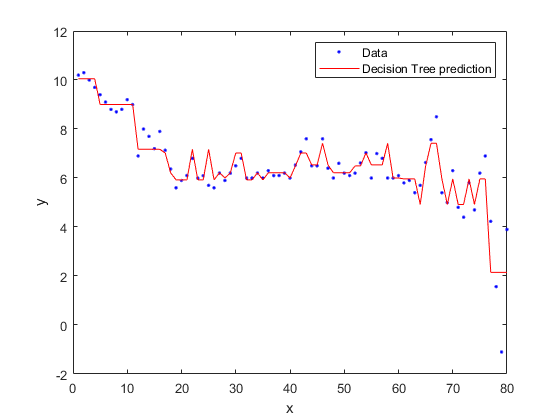

ypre2 = resubPredict(Dtreemodel);
plot(x,y,'b.',x,ypre2,'r');
xlabel('x');
ylabel('y');
legend('Data','Decision Tree prediction');
hold off;

% 线性回归
[LR, linearRMSE] =  LinearRegression(d3);
LRmodel = Dtree.RegressionTree;
imp2 = predictorImportance(LRmodel);
histogram(imp2);

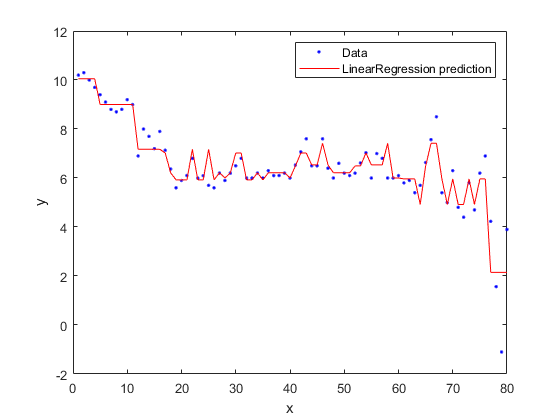

ypre3 = resubPredict(LRmodel);
plot(x,y,'b.',x,ypre3,'r');
xlabel('x');
ylabel('y');
legend('Data','LinearRegression prediction');
hold off;

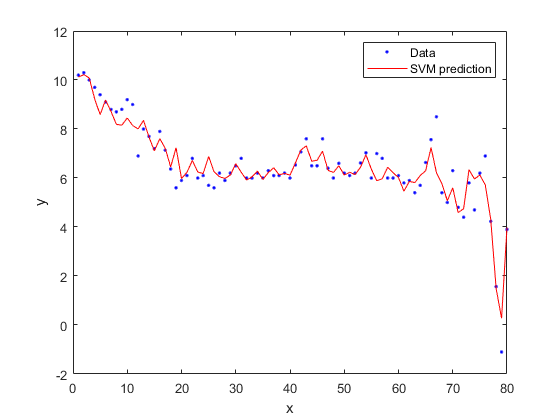

% 支持向量机
[SVMm, SVM_RMSE] =  SVM(d3);
SVMmodel = SVMm.RegressionSVM;
ypre4 = resubPredict(SVMmodel);
plot(x,y,'b.',x,ypre4,'r');
xlabel('x');
ylabel('y');
legend('Data','SVM prediction');
hold off;

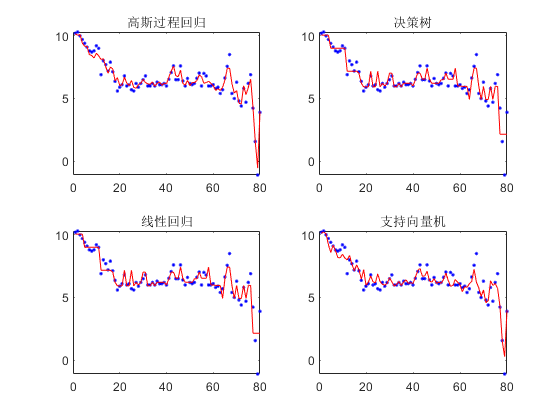

% 模型评估
subplot(2,2,1)
plot(x,y,'b.',x,ypre,'r');
title('高斯过程回归');

subplot(2,2,2)
plot(x,y,'b.',x,ypre2,'r');
title('决策树');

subplot(2,2,3)
plot(x,y,'b.',x,ypre3,'r');
title('线性回归');

subplot(2,2,4)
plot(x,y,'b.',x,ypre4,'r');
title('支持向量机');
hold off

% 预测接下来6个月的自变量数据
% 用前6个月数据的均值作为下一个月的预测值
[~,n] = size(d3);
Nan = nan(8,n);
d4 = [d3(end-3:end,:);Nan];
% d4从2020年1月份开始

% 全部指标在month月恢复疫情发生前6个月水平，即疫情持续month-1个月
% 2月份为疫情开始时间
month = 7; 
d3_ave = mean(d3(end-10:end-4,:));
d4(month,:) = d3_ave;
d4(1:month,:) = fillmissing(d4(1:month,:),'linear');

% 出口交货值（衡量有没有受国外疫情影响）
% d4(9,1) = d3_ave(1);
% d4(5:9,1) = nan;
% d4(1:9,1) = fillmissing(d4(1:9,1),'linear');

%疫情结束后的数据
if month < size(d4,1) 
    d4 = fillmissing(d4,'movmean',6);
end

d4(:,end) = [];
d4(1:4,:) = []; %1至4月份已有数据，不再预测
result_pre = predict(GPRmodel,d4)  %该项从5月份开始

result_pre =     4.5099
    5.0835
    5.4494
    5.0835
    5.2917
    5.4494
       NaN
       NaN


result_pred = [d3(end-3:end,end); result_pre]; %该项从1月份开始
result_pre = result_pred(3:month) %该项从3月份开始

result_pre =    -1.1000
    3.9000
    4.5099
    5.0835
    5.4494


%滞后性，3月份开始算起，但3、4月份已有数据，不再预测，保留5月份以后的数据

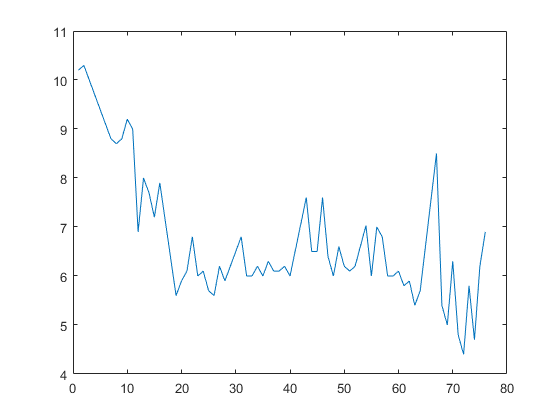

%% 不考虑疫情时的工业增长率
ratio = d3(1:end-4,end);
x1 = 1:length(ratio);
plot(x1,ratio)

d5 = [x1',ratio];
[R, validationRMSE3] = Ratio(d5);
Rmodel = R.RegressionGP;
xpre = 77:77+month-1; %从2020年1月份开始
xpre = xpre';
result_older = predict(Rmodel,xpre); %从2020年1月份开始
result_old = result_older(3:end) %滞后性，从3月份开始

result_old =     6.6373
    6.6694
    6.6999
    6.7290
    6.7566


## 损失估计

% 增长率损失，因为有滞后性，从3月份开始算起
% if month > 4
%     loss_ratio(1:2) = result_older(3:4) - d3(end-1:end,end); %3、4月份已有数据
%     loss_ratio(3:month-2) = result_old - result_pre; %5月份以后用预测值
% else
%     loss_ratio = result_old - d3(end-1:end,end);    
% end
loss_ratio = result_old - result_pre

loss_ratio =     7.7373
    2.7694
    2.1900
    1.6455
    1.3071


% 每个月的工业增加值_累计值
plusC = NUM(:,end-1);
plusC(1:8) = fillmissing(plusC(1:8),'linear');
for i = 1:9
    plusC(i*12-3:i*12+8) = fillmissing(plusC(i*12-3:i*12+8),'linear');
end

% 工业增加值损失等于去年同期的工业增加值_当期乘以增长率损失
plus = diff(plusC); %工业增加值_当期
loss_plus = plus(106:106+month-3).*loss_ratio

loss_plus = 	1.0e+05 *

    2.5099
    0.8984
    0.7104
    0.5338
    0.4261


loss_accu = sum(loss_plus);
fprintf('%i个月内完全恢复生产的工业增加值累计损失%.0f亿元\n',month-1,loss_accu)

6个月内完全恢复生产的工业增加值累计损失507848亿元


out = [result_old,result_pre,loss_ratio,loss_plus]

out = 	1.0e+05 *

    0.0001   -0.0000    0.0001    2.5099
    0.0001    0.0000    0.0000    0.8984
    0.0001    0.0000    0.0000    0.7104
    0.0001    0.0001    0.0000    0.5338
    0.0001    0.0001    0.0000    0.4261



loss_income = loss_plus/0.35;
loss_income_accu = sum(loss_income);
fprintf('%i个月内完全恢复生产的营业收入累计损失%.0f亿元\n',month-1,loss_income_accu)

6个月内完全恢复生产的营业收入累计损失1450994亿元


## 画图

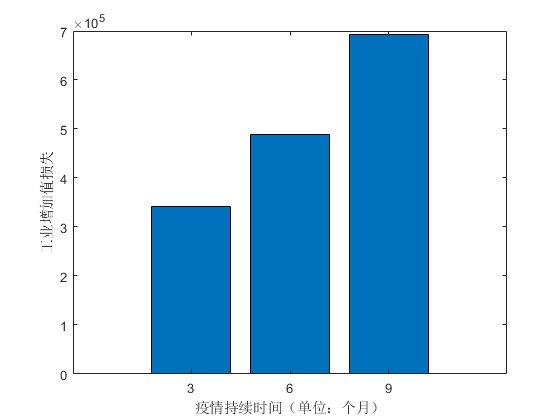

figure(2)
xx = 3:3:9;
yy(1) = 340822;
yy(2) = 488372;
yy(3) = 692711; %数据没变更
bar(xx,yy,'DisplayName','yy')
xlabel('疫情持续时间（单位：个月）')
ylabel('工业增加值损失')

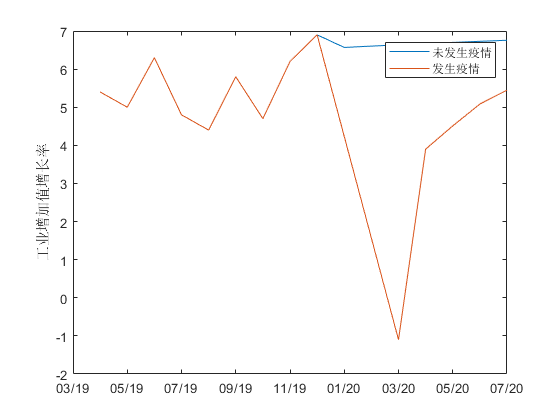


% 月份
xtick = {'11/19','12/19','01/20','02/20','03/20','04/20','05/20','06/20','07/20'};
xtick2 = {'03/19','05/19','07/19','09/19','11/19','01/20','03/20','05/20','07/20'};

% 增长率损失
figure(3)
r_old = [d3(end-12:end-4,end); result_older];
r_pre = [d3(end-12:end-4,end); result_pred(1:month)];
xre = 1:length(r_pre);
plot(xre,r_old,xre,r_pre)
set(gca,'XTickLabel',xtick2)
legend('未发生疫情','发生疫情')
ylabel('工业增加值增长率')

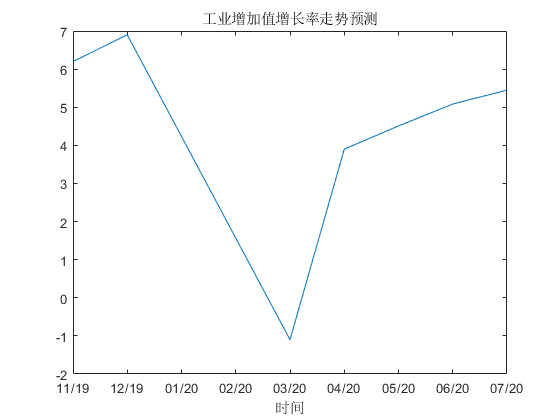

%xtickformat('M')

%增长率预测走势
figure(4)
ra = r_pre(end-8:end);
xra = 1:length(ra);
plot(xra,ra)
xlabel('时间')
title('工业增加值增长率走势预测')
%dateaxis('x',5)
%xtickformat('M')
set(gca,'XTickLabel',xtick)